root = 'D:\Data\confocalRelated\testData\imaging\intensitySum';
injectionT = readtable(fullfile(root,'injection.csv'));
injectionT = injectionT([6,10,11],:);

vars = cell(size(injectionT,1),3);
% col1: pixel intensity
% col2: pixel background intensity
% col3: least square cd
% col4, distance form injection site
% col5, pixel SNR

for anm = 1:size(injectionT,1)
    [out,vars{anm,2}] = getPointsSignalAndSectionBackground(root,injectionT.name{anm});
    vars{anm,1} = out(:,end-2);
    
    dist = calculateDist(injectionT(anm,:),out(:,1:3));

    [vars{anm,3},vars{anm,4},vars{anm,5}] = lsqr_3(dist,out(:,end-2));
    
    numel(vars{anm,5}) 
end

ans = 1785

ans = 1300

ans = 1320

signalMedian = cellfun(@(s)(median(s)),vars(:,1));
bgMedian = cellfun(@(s)(median(s)),vars(:,2));
[signalMedian,bgMedian]

ans =    502   224
   262   197
   279   192


% calculate SNR use median of all pixels

SNRm = cellfun(@(s,b)(median(s)-median(b))/std(b),vars(:,1),vars(:,2))

SNRm =    11.7429
    4.9354
    8.0258


% calculate SNR use 0.3 of all pixels

snrCells = cellfun(@(s,b)(s-median(b))./std(b),vars(:,1),vars(:,2),'UniformOutput',false);
SNRq = cellfun(@(snr)quantile(snr,0.3),snrCells)

SNRq =     8.1947
    3.6446
    6.5498


% determine colors

colors = redbluecmap;
%colors = colors([2:5,7:end],:);
colors = colors(end-4:2:end,:);
[~,idx] = sort(SNRq);
colors(idx,:) = colors;

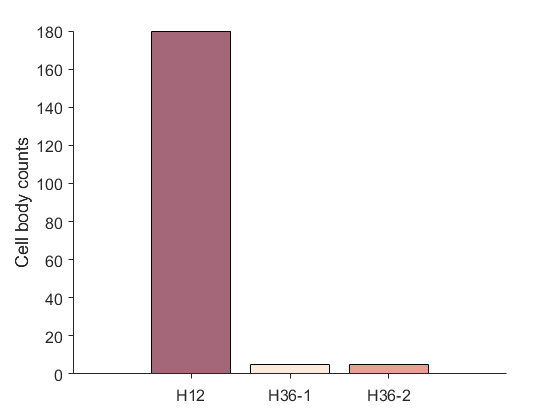

% bar plot cellbodies

f3 = figure;

b = bar(injectionT.cell_body_nums,'FaceColor','flat');
b.CData = colors;
b.FaceAlpha = 0.6;
ax = findobj(f3,'type','Axes');
ax.TickDir = 'out';
ax.FontSize = 12;
ax.YLabel.String = 'Cell body counts';
ax.Layer = 'top';
ax.XTickLabel = injectionT.name;
box off;

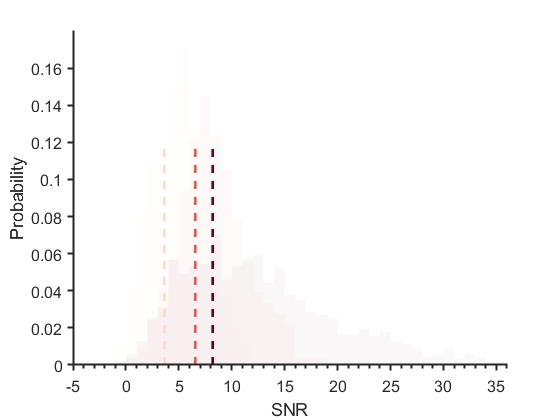

f2 = figure;
for anm = 1:size(injectionT,1)
    f2 = histogram_(f2,snrCells{anm},anm,colors(anm,:));
end
ax = findobj(f2,'type','Axes');
for anm = 1:size(injectionT,1)
    plot(ax,[SNRq(anm),SNRq(anm)],[0,2/3*ax.YLim(end)],...
        'LineWidth',2,'linestyle','--','color',colors(anm,:));
end
ax.LineWidth = 1.5;
ax.TickDir = 'out';
ax.FontSize = 12;
ax.XTick = -5:5:35;
ax.XLim = [-5,36];
ax.XLabel.String = 'SNR';
ax.YLabel.String = 'Probability';
ax.Layer = 'top';
ax.XMinorTick = 'on';

% plot pixel intensity and background
% subplot

violinplot(vars(:,1:2),injectionT.name,colors);

% plot pixel intensity and background
% plot on one figure

violinplot2(vars(:,1:2),injectionT.name,colors);

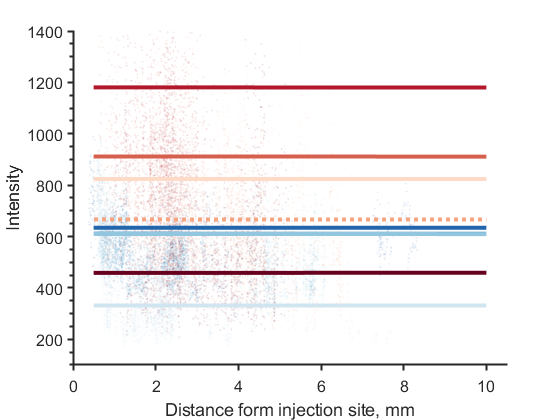

% intensity vs distance

f1 = figure;
for anm = 1:size(injectionT,1)
    f1 = scatter_(f1,vars{anm,4},vars{anm,5},anm,colors(anm,:));
end

for anm = 1:size(injectionT,1)
    if isequal(injectionT.name{anm},'H14')
        % H14 without imaging cell bodys
        ls = ':';
    else
        ls = '-';
    end
    f1 = line_(f1,vars{anm,3},anm,ls,colors(anm,:));
end

ax = findobj(f1,'type','Axes');
ax.LineWidth = 1.5;
ax.TickDir = 'out';
ax.FontSize = 12;
ax.YLim = [100,1400];
ax.XLabel.String = 'Distance form injection site, mm';
ax.YLabel.String = 'Intensity';
ax.Layer = 'top';
ax.YMinorTick = 'on';

function [out,bg] = getPointsSignalAndSectionBackground(root,name)
list = dir(fullfile(root,sprintf('%s_*_s.csv',name)));
out = [];
bg = [];
for f = 1:numel(list)
    name_ = list(f).name;
    ts = readtable(fullfile(root,name_));
    tb = readtable(fullfile(root,strrep(name_,'_s','_b')));

    intensity = ts.Mean;
    outlierTf = isoutlier(intensity);
    intensity(outlierTf) = []; 
    
    bg_ = tb.Mean;
    outlierTf_ = isoutlier(bg_);
    bg_(outlierTf_) = [];
    
    bg = [bg;bg_];
    intensity(:,end+1) = mean(bg_);
    intensity(:,end+1) = std(bg_);
    
    coordis = [ts.X(~outlierTf),ts.Y(~outlierTf)];
    coordis(:,end+1) = getSectionNo(name_,3);
    
    out = [out;[round(coordis),intensity]];
end
end

function z = getSectionNo(str,idx)
try
z = split(str,'_');
z = str2double(z{idx});
catch
    keyboard
end
end

function dist = calculateDist(injectionInfo,xyz)
% convect to um
xyz = xyz-...
    [injectionInfo.injection_colIdx,...
    injectionInfo.injection_rowIdx,...
    getSectionNo(injectionInfo.cell_bodys_at,2)];
xyz(:,1:2) = xyz(:,1:2) .* injectionInfo.resolution;
xyz(:,3) = xyz(:,3) .* injectionInfo.section_span;
dist = sqrt(xyz(:,1).^2 + xyz(:,2).^2 + xyz(:,3).^2);
end

function [cd,x,y,outlierTf] = lsqr_1(x,y)
% y 2 cols

y = -diff(y,1,2)./y(:,end);
%{
outlierTf = isoutlier(y);
x = x(~outlierTf);
y = y(~outlierTf);
%}
x(:,end+1) = 1;
cd = x\y;
x(:,end) =[];
end

function [cd,x,y,outlierTf] = lsqr_2(x,y)
% y 3 cols

y = -diff(y(:,1:2),1,2)./y(:,end);
%{
outlierTf = isoutlier(y);
x = x(~outlierTf);
y = y(~outlierTf);
%}
x(:,end+1) = 1;
cd = x\y;
x(:,end) =[];
end

function [cd,x,y,outlierTf] = lsqr_3(x,y)
% y 1 cols, gignal intensity

%{
outlierTf = isoutlier(y);
x = x(~outlierTf);
y = y(~outlierTf);
%}

x(:,end+1) = 1;
cd = x\y;
x(:,end) =[];
end

function fig = scatter_(fig,x,y,anm,color)
figure(fig.Number);
hold on;

s = scatter(x/1000,y,3,'filled','MarkerFaceColor',color);
s.Tag = sprintf('s%d',anm);
s.MarkerFaceAlpha = 0.11;

xlim([0,10.5])
end

function fig = line_(fig,cd,anm,ls,color)
xp = [0.5,1;10,1];
l = plot(xp(:,1)',(xp*cd),'color',color,'LineWidth',3,'LineStyle',ls);
l.Tag = sprintf('l%d',anm);

xlim([0,10.5])
end

function fig = histogram_(fig,snr,anm,color)
figure(fig.Number);
hold on;

h = histogram(snr,-5:1:40,'Normalization','probability');
h.Tag = sprintf('s%d',anm);
h.EdgeColor = 'none';
h.FaceAlpha = 0.03;
h.FaceColor = color;
end

function violinplot(inputCell,names,colors)
% inputCell{:,1} pixel signal intensity
% inputCell{:,2} pixel background intensity

np = py.importlib.import_module('numpy');
plt = py.importlib.import_module('matplotlib.pyplot');

N = size(inputCell,1);
ncols = 3;
nrows = ceil(N/ncols);

for anm = 1:N
    ax = plt.subplot(nrows,ncols,anm);
    parts = ax.violinplot(create_np_list(np,inputCell(anm,:),[]),pyargs('showmedians',true));
    
    pc = parts{'bodies'};
    plt.setp(pc,pyargs('color',colors(anm,:)));
    pc = parts{'cbars'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmins'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmedians'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmaxes'};
    pc.set_color(colors(anm,:));
    
    ax.set_title(names{anm});
    ax.yaxis.grid(true);
    ax.set_xticks(py.list([1,2]));
    ax.set_ylabel('Intensity');
    ax.set_xticklabels(py.list({'Signal','Background'}));
end

plt.subplots_adjust(...
    pyargs('top',0.963,'bottom',0.041,'left',0.041,'right',0.99,'hspace',0.234,'wspace',0.15));

plt.show();
end

function violinplot2(inputCell,names,colors)
% inputCell{:,1} pixel signal intensity
% inputCell{:,2} pixel background intensity

np = py.importlib.import_module('numpy');
plt = py.importlib.import_module('matplotlib.pyplot');

N = size(inputCell,1);

for anm = 1:N
    parts = plt.violinplot(create_np_list(np,inputCell(anm,:),[]),...
        [-1,0]+2*anm,pyargs('showmedians',true));
    
    pc = parts{'bodies'};
    plt.setp(pc,pyargs('color',colors(anm,:)));
    pc = parts{'cbars'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmins'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmedians'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmaxes'};
    pc.set_color(colors(anm,:));
end

ax = plt.gca();
ax.yaxis.grid(true);
ax.set_xticks(py.list((1:2:N*2)+0.5));
ax.set_ylabel('Intensity');
ax.set_xticklabels(py.list(names'));

ylim = ax.get_ylim;
ax.vlines((2:2:2*(N-1))+0.5,ylim{1},ylim{2},[0.8,0.8,0.8],'dotted');
%{
for anm = 1:N
    ax = plt.subplot(nrows,ncols,anm);
    parts = ax.violinplot(create_np_list(np,inputCell(anm,:),[]),pyargs('showmedians',true));
    
    pc = parts{'bodies'};
    plt.setp(pc,pyargs('color',colors(anm,:)));
    pc = parts{'cbars'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmins'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmedians'};
    pc.set_color(colors(anm,:));
    pc = parts{'cmaxes'};
    pc.set_color(colors(anm,:));
    
    ax.set_title(names{anm});
    ax.yaxis.grid(true);
    ax.set_xticks(py.list([1,2]));
    ax.set_ylabel('Intensity');
    ax.set_xticklabels(py.list({'Signal','Background'}));
end

plt.subplots_adjust(...
    pyargs('top',0.963,'bottom',0.041,'left',0.041,'right',0.99,'hspace',0.234,'wspace',0.15));
%}
plt.show();
end

function list = create_np_list(np,cell_,list)
if isempty(list)
    list = py.list();
end
list.append(py.list(np.array(cell_{1}')));
list.append(py.list(np.array(cell_{2}')));
end